
% to do
% 1) get 2-way, 3-way bar graphs
%   - scatter ball-only vs rest?
% 2) commonality analysis
% 3) debug venn.m

% why sometimes PVAF(A)> PVAF(AUB)? due to cross validation? then for training data,
% alway PVAF(A)<PVAF(AUB)

% dependence: axisEqual applytofig4keynote

load run_glm.mat

% histogram of R2 for full model
% separate histogram for vis/occ (# neurons are slightly different)

id_full_model=1;
PVAF_vis=PVAF_model_vis(:,id_full_model);
PVAF_occ=PVAF_model_occ(:,id_full_model);

% plotting spec
nBin=20;
b=linspace(min([PVAF_vis(:);PVAF_occ(:)]),max([PVAF_vis(:);PVAF_occ(:)]),nBin);
cmap=viridis(2);

% main
figure; hold all;
i_bin=1;
[n,x]=plot_histogram(PVAF_vis,b,i_bin,cmap);

    5.2449



disp([x*100; n]);

  Columns 1 through 9

  -10.5826   -5.6009   -0.6191    4.3626    9.3443   14.3260   19.3077   24.2894   29.2711
    3.0000   90.0000  613.0000  381.0000  138.0000   65.0000   44.0000   18.0000   13.0000

  Columns 10 through 18

   34.2528   39.2345   44.2163   49.1980   54.1797   59.1614   64.1431   69.1248   74.1065
    8.0000    5.0000    2.0000    4.0000         0         0    1.0000         0         0

  Column 19

   79.0882
         0




i_bin=2;
[n,x]=plot_histogram(PVAF_occ,b,i_bin,cmap);

   10.1450



disp([x*100; n]);

  Columns 1 through 9

   -8.0917   -3.1100    1.8717    6.8534   11.8351   16.8168   21.7986   26.7803   31.7620
   11.0000  191.0000  749.0000  596.0000  332.0000  202.0000  139.0000   88.0000   69.0000

  Columns 10 through 18

   36.7437   41.7254   46.7071   51.6888   56.6705   61.6522   66.6340   71.6157   76.5974
   48.0000   39.0000   38.0000   25.0000   14.0000   13.0000    6.0000    8.0000    6.0000

  Column 19

   81.5791
    2.0000



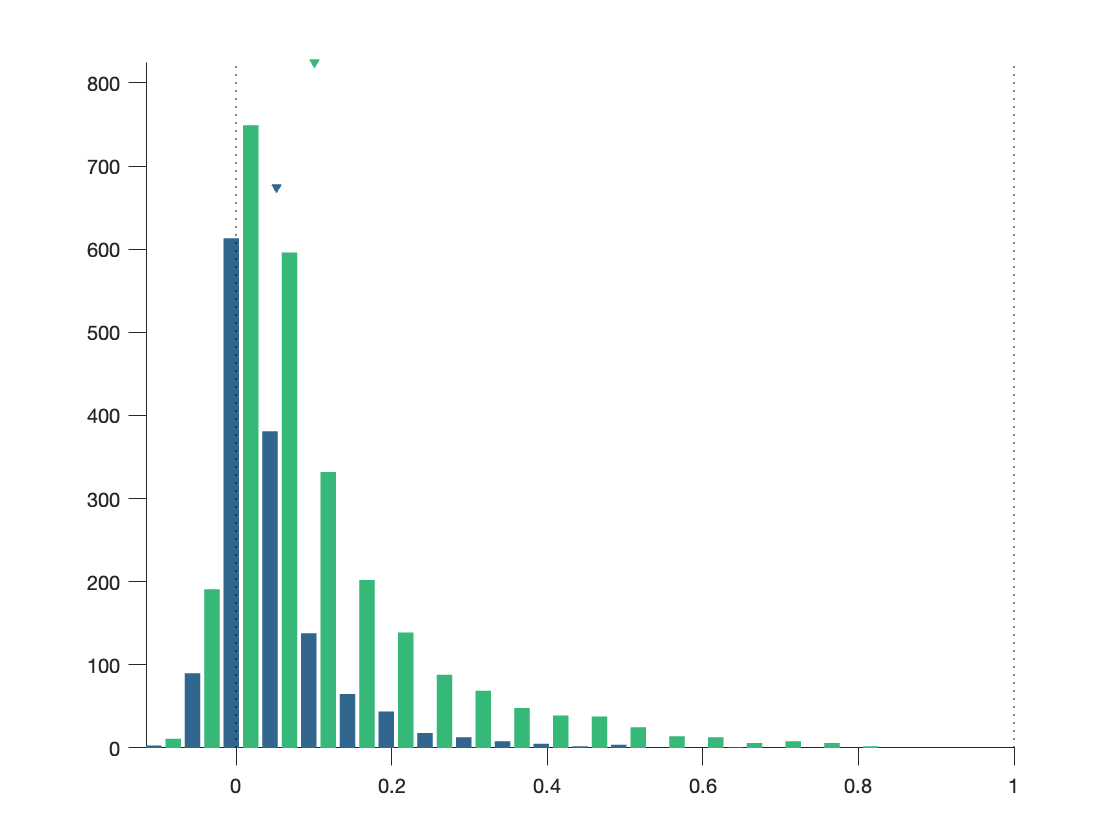


drawnow; pause(0.5);

   11.4286
    9.4706
   10.5556
    9.8810
   10.0690
   11.4375
   11.3429
   12.2778
   12.1667
   10.1081
   14.4500
   11.2647
   10.2059
   12.6765
   11.1714
   11.0750
   11.1667
   11.2500
    8.0541
    9.7949
   11.8125
   13.8387
    8.0882
   10.8333
    8.9737
    7.5263
    9.8235
   11.6757
   11.0303
   12.2812
    9.0345
   10.0833
    9.1250
    8.3421
   11.7143
   10.5588
   10.1389
   10.7500
   11.7500
    8.2727
   11.4250
    9.4545
    9.5714
   10.3429
    9.6923
    8.2632
   10.7297
    9.5750
   10.3514
    9.9429
   10.5429
    8.5135
   10.4062
   10.9143
    9.0571
   10.2778
   10.9355
   10.3714
    7.8108
   11.9394
    9.4571
   10.0000
    7.8947
    8.2069
    9.8182
   12.0588
   11.5000
    9.6176
   10.1389
   10.8182
   10.9474
   10.1622
    8.8108
    9.9143
   10.3793
   10.7188
   10.7895
    9.1707
    9.3636
    9.8438
   11.5128
   10.9459
    9.8286
    9.7714
   10.0513
    9.5263
   11.6176
   10.0000
   10.1111
    8.8831
   10.3514

   10.2286
   11.2286
   11.5526
   12.1429
    8.6667
   10.1000
    9.7714
   10.5429
    8.8108
    8.2286
    9.1765
   12.2500
   10.0645
   10.8857
    9.1714
   12.2353
   13.3056
    8.9143
    9.9091
   14.0000
   13.4848
    9.5000
   13.9706
   10.6452
    9.7500
   11.2564
   14.6579
    9.9024
    8.5844
   14.1875
   11.8857
   11.1212
   10.1714
   11.8158
   12.3939
   11.6970
    8.0000
    8.3714
   10.7000
   11.1515
   10.5882
    9.0976
    8.2812
    9.8824
   10.0000
   10.4103
   10.8421
    8.0645
    9.3243
    9.4412
    8.9487
    9.9250
   10.6923
   10.7333
    9.6410
    8.5405
    9.7941
    9.9737
   10.5152
   10.6111
   11.5588
    9.3429
   11.5484
   10.0370
   10.9429
   10.8378
    7.4194
    8.5455
   10.7895
    9.3158
    9.0938
    9.2703
   11.9118
   11.0909
   11.2000
    8.8571
    9.3143
   11.5882
   10.9333
    9.7838
   10.2647
    9.1212
   10.4375
    9.9310
    9.6486
    9.9000
    7.5526
   12.4211
   10.8710
   11.7429
   10.6774

   10.9000
    9.1579
   10.1765
   11.4000
    8.7059
   10.0294
   10.5000
   10.2973
   11.7097
   11.1667
   10.8500
    9.9000
   10.1143
    8.9714
   11.3235
   11.1389
    8.7941
   11.9412
   11.3590
   11.5000
   11.0571
   10.0588
   11.4118
    9.3333
    9.0312
   11.4872
    9.4762
   11.7143
   10.9394
    9.1724
   11.5000
    9.3529
   10.5588
   12.7188
   14.1351
   11.4848
   11.0882
    8.4474
    8.6571
   12.8108
    8.0000
   10.6667
    9.0857
   10.6571
    8.9730
   11.3421
   10.8824
    8.6286
    6.8710
    9.2414
   10.5806
    9.6286
    9.7941
   10.1471
    8.3824
    9.2571
    9.1538
   10.2105
    9.3514
    8.6250
    9.4706
   10.6471
   12.0000
    9.7436
   10.9375
    8.8701
    8.7241
   11.7188
   11.0500
    9.7647
    8.8000
   10.1053
    9.0513
    9.2222
    9.6774
   10.6667
    9.7143
   10.7000
    7.8947
   10.1765
   10.5000
    9.5938
    9.3333
    8.5294
   10.3939
    8.9714
    8.8857
    8.4595
   11.3514
   10.1471
   10.2353

    9.5000
   11.1026
   11.4054
   11.6176
    9.8333
   12.2941
   11.0000
    8.7097
    8.4324
   11.5000
    9.9394
   10.6923
   13.8065
   10.8276
    9.9412
   11.7647
   11.5333
   10.8250
    9.5946
    9.6857
   10.1176
    8.5714
   10.7000
    8.8108
   11.4444
   14.6571
    7.9677
   10.4857
    9.5517
    7.8788
    8.0000
    9.3636
    9.8235
    9.4595
   10.9091
   10.4250
   10.7500
   12.4412
    8.4857
    9.9756
   10.7222
   10.0000
   10.2059
    9.0270
   10.5588
    8.2143
    7.5758
    8.8857
   10.8824
   11.7812
   10.7742
    9.7037
   11.0571
   11.5278
    9.2069
   11.2778
   10.0000
   10.5152
    8.8500
    9.5556
    8.0294
    9.0476
   10.2424
    9.1471
   10.4286
    9.5806
    9.5833
    9.5000
    9.6857
   10.4167
    9.5238
    8.6176
    8.4865
    9.7143
    9.3333
   11.0571
   11.5000
    9.2647
    9.7778
   10.5385
    9.8519
   10.1389
    8.9118
    9.9394
    9.4118
    8.3784
    8.7273
   10.6571
   10.4571
    9.4545
   11.5938

    9.4103
    9.5938
    9.1500
   10.7949
   10.2000
   11.6053
   13.3750
   11.9250
   13.0526
   11.1039
    9.6667
   11.8857
   13.2333
    8.4737
    9.5946
   12.0938
    9.1429
    9.0345
   11.3226
   12.6000
   11.4706
    9.8182
   11.3250
   11.7667
   11.7838
   13.5641
    9.0952
    9.7838
   11.9091
    8.2571
    9.9412
    9.6098
    9.0938
   10.8250
   10.8611
   12.1944
   10.9259
   11.5625
   11.1429
    8.0909
    8.3143
    9.6667
   11.3611
   10.4062
   10.7037
   11.2778
    8.4324
   10.4211
   10.0000
    8.7222
   11.6970
   11.7353
   10.3667
    9.2647
    9.1282
   11.3824
    8.8684
   10.0588
    9.6944
   10.1081
    9.6970
    9.1818
    8.1429
    9.8571
    9.2571
    9.0345
    7.9091
   10.3333
   10.3333
   11.4474
    9.2647
    8.4000
   10.0588
   11.6765
    9.4878
   10.6471
   11.4444
    7.8571
   10.0250
    9.5000
    7.5714
    9.1282
   10.9737
   10.6000
   10.4062
    9.6111
   11.9429
    7.5143
    9.7714
   10.0571
    9.1351

    9.5172
    9.0000
    8.7027
    8.8158
    8.8780
   12.4375
    9.6765
   10.1282
   12.2222
    9.9722
    9.4545
   11.2051
   10.7188
    9.8148
   12.0000
   11.0571
    8.2581
    9.6364
   10.0588
    9.8462
   11.4872
    9.7073
   11.0571
   13.3333
   12.6571
   12.2432
    9.1471
    9.7241
    9.9394
   10.1795
   10.5000
   11.1026
   10.8205
   12.9677
   13.1429
    9.0303
   11.8235
   13.4706
   11.8857
   10.3939
   12.3333
   10.3030
   13.2000
   12.0556
   13.0278
   11.2581
   12.8667
   10.8710
   10.9412
   11.3000
   10.8205
    9.5862
    7.3684
   11.8857
   10.2821
   12.3421
   11.2162
   10.6364
    8.1471
   10.4000
   10.2667
    9.5882
    8.5714
   10.6061
    9.6000
    9.0000
   10.6389
    7.7742
    9.1795
    9.2812
    9.4118
   11.0000
    9.3750
   10.6154
   10.8438
   10.2571
   10.5484
    9.0769
    8.3714
    9.1714
    8.7568
    9.7949
    9.5152
    8.4595
    8.1795
   10.2250
    8.9697
   10.8056
   11.7097
    8.6494
   11.1111

    9.0294
   10.6316
    8.4688
   10.5405
   10.9722
    7.6000
    9.8158
    8.8158
    8.5152
   11.0270
   11.3056
    9.9062
    8.8000
    8.3030
    8.2000
    9.0857
    8.6757
   14.6154
   12.2973
   15.3438
   14.4000
   13.5333
   10.0857
    8.4000
    9.1143
   11.3429
   11.3824
   10.3846
   14.0263
    8.6897
    9.4706
   12.7647
    9.0541
   11.1765
   11.1176
   10.9444
    8.2727
    8.9412
    9.5641
    9.8235
    9.4054
    9.8974
   11.6500
   10.9091
   11.4595
    9.8056
    9.0625
   10.2667
    9.8158
    9.2000
    7.5789
   10.8333
   11.4857
   10.9394
   11.9375
   10.7097
   11.2059
   10.4062
   10.8889
    8.5143
    9.3171
   10.4722
   10.6216
    9.5455
    9.7949
   11.7000
    9.4286
    9.3438
   10.7895
    9.6667
   10.4359
   10.8148
   11.1875
   10.0556
    9.5714
    9.1081
    9.9750
   10.2571
    9.7000
    7.8065
    9.8333
   10.9355
    9.2051
    9.1515
   10.7812
    8.9429
    9.5758
    8.8462
    8.5833
   10.2222
    9.6765

    9.5556
    9.5758
    8.3333
   10.3056
   11.7000
    9.3243
   11.7532
    9.3529
   10.4839
    8.5143
    8.3125
   12.0588
   10.6765
   11.2812
   10.6667
   12.2424
    9.7419
   10.0000
   10.4545
   10.1463
   11.4444
   11.2432
   10.0000
   12.4688
   16.2286
    7.6774
   12.2500
    8.7632
   13.5294
   13.8500
    9.6571
    9.7778
    7.5714
   10.9688
   12.8065
   13.8000
   10.5161
   11.4839
   10.4211
   13.0588
   11.1944
   10.4615
   12.0571
   12.2286
    7.0588
   11.7500
    9.3077
   11.3889
   10.2727
   10.1667
   10.1667
    9.7949
    9.5556
    9.5806
    9.8857
   10.0000
   11.0333
    8.8857
    9.1951
   10.4333
   11.0286
   10.6389
   12.1935
    9.3429
   10.4706
   10.7333
   10.7273
   10.5625
    9.6061
    9.8000
    9.2564
    9.0286
   10.1111
   10.9062
   11.7647
   12.4500
    8.0606
   10.4667
    8.6842
    8.4688
   10.7429
   10.8125
   11.5161
   11.0286
   10.2059
   10.6875
    9.7250
   10.6944
    9.7576
   10.3143
    9.5938

    9.5882
    8.9714
    8.6970
   10.2703
    9.3333
    8.6765
   10.1000
   10.2727
   10.6667
   14.7714
   10.6111
    7.5484
   13.1562
    9.8056
    8.9688
    8.3421
   11.4167
    8.9189
   10.3030
   12.3704
   12.0606
    8.7429
    9.3611
    9.1316
    7.7632
   10.2564
   13.9444
    9.1351
    8.5143
   10.2222
   11.1212
   11.7500
   10.9500
   11.3714
    9.1538
   12.5000
   12.0571
   10.5278
    9.3590
   11.3333
   13.2500
   13.6571
   14.0857
    8.2857
   10.6364
    8.7143
    8.8235
   10.5000
   10.2353
    9.7879
   11.4194
   10.4444
   10.3226
   11.0303
    8.4324
    7.5641
   10.5714
    9.7188
   11.5882
   10.2059
    9.5143
    8.8919
    9.8182
    8.3810
   11.7500
    9.5897
    7.9091
    9.5312
   10.3158
   10.5526
   11.5000
    9.7667
   10.1176
   11.2286
    9.0811
   11.1875
    8.9740
    9.8611
   11.2162
    7.8387
    7.0000
    8.9744
    9.2051
   10.0294
    9.3846
   11.2647
   10.8684
    9.3117
    8.2069
    9.5806
   10.1667

    9.1316
    8.3429
   10.4242
   11.8718
    9.0000
   10.2424
   10.5862
    8.4474
    8.9062
   10.2121
   12.8529
    9.1892
   12.2571
    9.7105
   12.3684
   11.6571
   12.7188
   12.8333
    8.8824
   11.2821
    9.0000
   11.7222
   10.8205
    9.5000
    8.1081
   10.3077
   11.0882
   12.3056
    8.6571
   10.8462
   12.1795
    7.1935
   11.3889
    9.2703
    9.1818
    8.3438
   10.1250
   13.5588
   10.8205
    7.8571
    8.4483
    7.1143
    8.9730
    8.6571
   11.1333
   10.8125
    7.2414
    9.0000
    9.9714
   10.1515
    8.7714
    8.4286
    8.2105
    8.9189
   11.2222
   10.2432
    9.1795
    8.4062
   11.6176
   10.0541
   10.1000
   12.0286
   10.4444
    9.8276
    9.9412
   10.0000
   10.4688
    9.6667
   10.9677
    9.5000
   10.5429
    8.0263
    8.5143
   12.2059
   10.0588
   11.1667
    8.8095
   11.7250
   12.0606
    8.5143
    9.2821
    9.2439
   12.2059
    9.5938
    9.0714
    9.0256
    9.8000
   10.4062
    9.6111
   11.8108
   11.0303

   12.0714
   17.2222
   15.0000
   16.7778
    9.3750
   10.1667
    8.8000
    9.2500
   13.8000
    8.6667
    7.8571
   11.8333
   12.6667
    8.7500
    7.1429
   10.0000
    9.8333
    9.9000
    9.0909
   14.8889
   11.8750
   10.2222
   15.5556
    8.4444
    7.3333
    8.2500
    7.6667
   10.6000
   13.6667
    9.8000
    5.2222
    6.9286
    8.6000
    5.0000
    7.3333
   13.7000
    9.5000
    7.0000
    8.3750
    6.9000
    3.7500
    7.4000
   12.8000
   18.7500
   13.2500
    9.8125
    7.4000
    5.3333
   12.6667
    7.7000
    8.7500
    7.3636
    7.6000
    8.2500
    5.0000
    7.7500
    7.5000
    9.0000
    8.6875
    6.7778
    5.0000
    4.8889
    8.8889
   15.6667
   11.1111
    7.6250
   12.1111
   12.0833
    9.4286
   13.0000
    7.6667
    5.9091
    8.2500
    8.6667
    6.6000
    6.7500
    8.7500
    9.1000
    8.7000
    7.8333
    9.1667
    7.5000
   13.2500
    7.4000
    9.8000
    6.2308
    6.1667
    6.0000
   11.6000
    8.7000
    8.6000

   13.4286
   16.2000
   12.2000
   14.0000
   10.1538
   15.7778
   23.8889
   14.2222
   14.1000
   15.5000
   12.4167
    8.0000
    9.8750
   10.6154
   14.6000
   14.6000
    9.4545
    9.6250
   12.1429
    8.7273
    6.8333
   10.2500
    9.2500
   10.2500
   14.4444
    6.5000
    9.6667
    6.0000
   11.1111
    9.0000
   10.2000
    8.6364
    7.3333
   10.0000
   11.2500
    6.0000
    9.2500
    9.6000
   12.4000
    6.7500
    7.6000
   10.5000
    3.7500
   10.3000
   14.7778
    9.1250
    7.1000
    6.6364
   14.2222
   10.6000
   10.0000
    8.1250
   12.4444
    9.3333
    9.3333
    7.1250
    6.8333
    8.0000
    3.0000
    8.6000
   10.0000
    8.5000
    8.5000
    9.0000
   15.4444
   10.0000
   14.2500
    9.0000
    7.8889
    9.7143
    7.8333
   11.6429
   13.3636
    9.6250
    9.6000
   12.7500
    5.9091
   10.4286
   13.2000
    4.2500
    4.7500
    4.8750
    9.2857
   11.3750
    8.5000
   12.0000
    9.8333
    9.8000
   15.8000
    2.7500
    6.3333

   15.4444
   16.4000
   10.5455
   13.9167
   11.2500
    7.2500
    8.6667
   10.5000
   10.4167
    7.0000
   11.0833
    9.4000
    8.4444
   11.5556
   13.2000
   13.0000
   13.0000
   10.1000
    9.1250
   10.6000
   15.8889
    5.3750
   12.3750
   10.6667
    6.6250
    8.7692
    9.3750
   10.6364
    9.1667
    6.0000
    6.2222
    7.6000
   12.2222
    8.9167
    8.7500
   10.3333
    9.9091
    7.5000
    7.0000
    7.2500
    8.5714
   10.6250
    9.7500
   11.6667
    7.6000
    5.5000
   13.1667
   10.7500
    9.5000
    7.4000
    9.5000
    5.0000
    7.1111
    6.8333
    7.8333
   13.2000
    9.0000
    5.4286
    7.0000
    8.5714
    5.0000
    9.4000
    5.2500
    9.8571
   14.2000
    9.1000
    9.0000
    9.6000
   11.0000
    6.0833
   14.5000
   12.7778
    9.3750
    6.5000
    8.0000
   10.7500
    8.2500
   14.4000
   12.3333
    6.3750
   10.3333
   10.2222
   13.3333
    5.4000
    9.5455
   10.3750
    7.7000
    7.0000
    7.3333
    5.0000
   11.4000

   17.5000
    6.3333
   15.1000
    9.0000
    7.6364
   13.6000
   10.7000
   10.5714
   19.7778
    4.1667
   10.0000
   14.7143
    9.9231
    8.3636
   13.3333
    8.7273
   17.0000
    9.2500
    9.6364
   12.1111
   11.2500
   12.8000
    7.5000
    8.3750
    9.2500
    9.5000
    9.0000
    5.5000
    6.8571
    9.0000
    8.6364
    6.1667
    6.8750
   14.5833
    9.5000
   12.6667
    7.2000
    7.7000
    9.4000
    7.1250
    8.1000
    6.8462
    9.6667
   14.3636
   10.1000
    7.7273
    6.3750
    8.3333
    9.9000
    7.4444
    6.0000
    9.0000
    6.5833
   12.0909
   18.4000
   11.8750
    8.2500
    8.3333
    6.0000
    5.7778
    9.4000
    5.7778
   12.2222
    7.6250
    9.7500
    6.2222
    7.6154
    9.6667
   11.0000
   18.0000
   11.0000
   10.4000
    8.0000
    9.3000
    9.2727
    9.5000
    8.6000
    6.1000
    5.7500
   10.2222
   14.3750
    7.0000
   12.2857
   11.1250
   11.1429
   10.0000
   10.1429
   11.5000
    4.5000
    6.5625
    6.7500

   13.7778
    6.0000
   13.2000
   10.1000
    8.4545
   12.6000
   13.5000
   10.2500
   12.1000
   13.1429
   14.2000
    9.3077
    9.2500
    9.8000
    3.8750
   11.4000
   10.6364
   13.0000
   10.4000
    9.5385
   17.0000
   10.6667
   16.1000
    5.3333
   15.1111
    8.5000
   11.5000
    8.7000
    8.0000
    7.1111
   11.6000
   12.3000
   11.8750
    6.5000
   19.7778
    9.8000
    9.2000
   13.0000
    9.0000
    6.4545
    6.5000
    4.8333
    7.0000
    9.8750
    7.5556
   10.2000
    5.0000
    5.5000
    8.6667
    6.4000
    8.8000
   10.3333
   10.4000
    5.3333
   17.6000
    9.8750
    6.3636
    5.6250
    6.8750
    9.0000
   10.0000
   10.8571
   10.1000
   12.7778
    6.1250
   13.8889
    9.5000
    6.5000
    6.2500
   11.7500
    7.3000
    7.0000
    7.7500
   10.5000
    7.7500
   13.0000
   12.8571
   14.3333
   11.1667
    8.1000
    8.4444
   11.0714
   10.0000
    6.8000
   12.6667
    3.5000
    7.1250
   10.2500
   11.2222
   13.2000
    4.0000

   14.7000
   10.2000
   15.2222
   11.9167
    7.9167
    7.5000
   11.2500
   13.8889
   12.8750
   10.0000
    6.7500
   10.2000
   11.2500
   10.9000
    4.7500
    9.2000
    6.5556
    9.7500
    8.8750
    8.4000
    8.4167
   10.7000
    9.1000
   10.3333
    9.6667
    7.1250
    9.1000
   20.8000
    8.5000
    7.3333
   12.8889
    9.9167
   14.0000
   11.2500
   11.2500
    7.9091
    6.3750
    7.3333
    8.4000
    6.6667
    7.1667
    7.2500
    6.4444
    9.8333
    7.4167
    6.5000
   10.5714
    8.1250
    5.2500
    7.0000
   15.3750
    7.5455
    5.0000
    7.0000
    8.8000
    9.1111
   14.2500
    9.1667
    9.6667
    7.8750
   11.8333
   13.0000
    9.0000
    8.6000
    7.2500
   15.7778
    7.0000
   10.8182
    8.0000
    7.6667
    9.0000
    8.2000
    8.0000
   12.2857
   10.1111
   11.3571
    7.8333
    8.7000
    7.5000
    6.7500
    9.6667
    9.0000
    8.2500
    8.1250
   13.7500
    8.0000
    9.6667
    8.6000
    7.9000
   11.5000
   13.5000

    6.7500
   22.8889
   13.8000
   10.5455
   15.0000
   15.7778
   11.1000
   11.9231
    9.2857
   18.1111
   11.5556
   11.2308
   10.1000
    9.8750
    9.1429
   14.2000
   11.1111
   10.7500
   10.3636
   10.1250
   17.1667
    6.0000
   10.2500
   14.7778
    8.5714
    9.0000
   12.5000
    8.8182
    9.5714
    8.8462
    6.8750
    8.6667
    7.6000
   11.1250
    8.0000
    9.6667
    6.2143
   10.4444
   10.5714
    8.6000
    7.5000
    7.3077
   15.5556
    5.7500
   14.2500
    8.9000
    7.0000
    6.2000
   12.5000
   10.3000
    4.2500
    8.7500
    6.9000
    8.3333
   13.2500
   12.5000
    5.1667
    7.1250
    7.4000
    9.7500
   12.8889
   10.6429
    9.8889
   12.4000
   12.3333
   10.0000
    6.5000
    8.8000
   13.8889
   12.2222
    9.6000
    4.5000
    7.1250
    7.6250
    9.4444
    9.7857
    9.8333
   12.0000
   13.9286
    7.8889
    5.5000
   12.0000
    7.1250
    7.7500
    9.1250
    7.1000
   11.5000
    9.4000
   11.0833
   13.0000
   12.8000

   13.6000
   15.7143
   11.6667
   13.8571
   14.5000
    6.7500
   15.8000
   17.3333
   10.6667
   13.3333
   14.0000
   13.1000
   12.3333
   12.2727
   14.3333
   16.5556
   11.2500
    9.5625
   10.2500
   10.2500
   15.1111
    8.7778
   11.0833
   12.2222
    8.3333
   10.1250
    7.7500
    9.2500
    7.7000
   11.2500
   12.9167
    7.2222
    9.2000
   11.2500
    7.2857
    7.5000
   10.1250
   18.3750
    9.7500
    6.9000
   10.1250
   10.0000
    9.0000
    8.1667
    6.8000
    6.8182
    4.7500
    8.0000
    9.2500
   10.4286
   11.2222
    9.0000
    5.8889
    7.7000
    6.3750
   10.0000
    8.0000
    7.5000
   11.4286
   12.2500
    8.1667
    5.1250
    6.6154
    6.1667
    7.0000
   16.6000
    8.2500
    5.0000
    5.1250
    6.5000
    9.0000
    7.7500
   14.4000
   10.0000
    4.7500
    6.8000
    6.4444
    9.1111
   14.0000
   14.3333
    8.5000
    5.5000
    3.8333
   10.4000
    9.1250
   12.7857
   10.0000
   10.2857
   11.8750
   11.2500
    4.7500

   15.6667
   10.6667
   16.4286
   14.2000
   10.3846
    7.9167
   17.2222
    8.3750
   10.0714
    9.5000
   10.6250
    6.0000
   10.2000
    9.9167
   14.0000
    7.8889
   11.3000
    7.0000
    7.4286
    8.6000
    8.1667
    9.2000
    8.7692
   11.1250
   15.2000
   15.5833
   10.1250
    8.5000
   12.2500
    7.0000
    7.2500
   19.0000
   14.3636
    9.3000
    9.0000
    9.2000
    6.6154
   14.3636
   18.4000
    8.6000
    9.3000
   16.8889
   13.7778
   20.8000
    7.2500
   12.0000
   10.8333
    8.5000
    7.8333
    5.8333
    7.6667
    5.2222
    7.6154
   12.3333
   10.3750
    5.4444
   14.6000
    6.0000
    8.3333
    6.9000
    9.2500
    5.0000
    8.6000
    6.2500
   13.5000
    8.3333
    4.5556
    6.8000
    9.8889
    6.6250
   11.2500
   11.4000
   10.6250
   13.2000
   16.2500
    7.0000
    5.2500
    8.4000
    5.4000
    5.6250
   15.0000
   10.3333
   12.2000
    7.5000
    7.8750
   15.6667
    5.2500
    5.5833
    8.9167
    4.6000
   13.0000

   13.9000
   16.3000
   11.7000
   22.2222
   15.1429
   13.0833
    6.2500
   10.8000
   10.6667
   11.4000
   16.0000
    8.9000
    8.1111
    9.5000
    5.5000
   12.8333
    7.5000
    9.0000
    9.8333
    9.2857
    9.5000
   11.0000
    9.2222
   10.6000
   10.0000
    9.3333
    9.9091
    8.0000
    9.8000
    9.8000
   17.0909
    8.9000
   13.3333
    6.6000
   14.2222
    7.7778
    9.4000
   11.5000
    8.2000
   12.7500
    9.3333
    7.3333
    8.7500
    5.7778
    9.9000
    8.8125
    6.0000
    7.7500
    8.8000
   13.2222
   15.0000
   12.2500
   13.2727
   10.6000
    6.7500
   13.8333
    8.5000
    7.6667
    5.8333
    6.8889
   10.6250
   14.3333
   10.3333
   12.5000
    7.4545
   11.7500
   10.8000
   13.4000
   10.3333
    8.3000
    8.8750
    8.1111
    9.1667
    6.5000
    6.9231
    7.9000
    6.4000
    5.0000
    8.1250
    8.8125
   12.5000
   10.8889
    9.2222
    6.8750
    9.0000
    6.0000
    9.2500
   11.5000
   12.8889
    9.7778
   11.5714

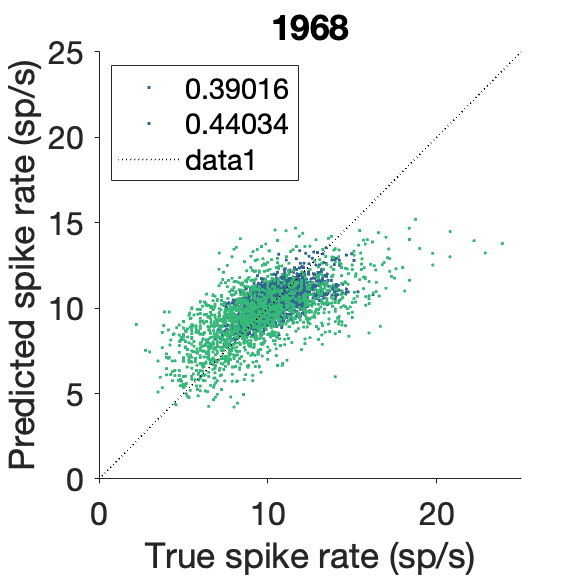

% plot example neuron's predicted vs actual responses (full model)
eg_neuron_id=1968; % [427;452;475;476;801;808;893;1000;1014;1107;1172;1244;1251;1451;1491;1545;1836;2105;1968;2157];
% 1014; 1593; 2628];
for i=1:length(eg_neuron_id)
    plot_eg_glm_fit(eg_neuron_id(i));
    
    title(eg_neuron_id(i));
    
    legend({num2str(PVAF_vis(eg_neuron_id(i)==idx_vis)),...
        num2str(PVAF_occ(eg_neuron_id(i)==idx_occ))},...
        'location','best');
    
    drawnow;
    axisEqual;
    set(gca,'tickdir','out');
    plotIdentity(gca);
    ylabel('Predicted spike rate (sp/s)');
    xlabel('True spike rate (sp/s)');
    applytofig4keynote;
end


drawnow; pause(0.5);

% plot PSTH or spatial modulation?

## plot PVAF bar

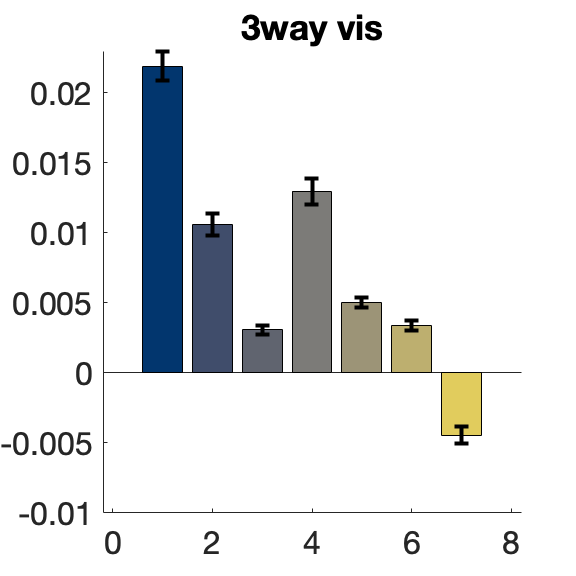

% set up indices
id_median=0; % if 0, mean

sets={'ball','eye','hand'};
labels={'ball','eye','hand','ball & eye','ball & hand','eye & hand','full'}; % A, B, C, A&B, A&C, B&C and A&B&C.
colors=[1 0 0; 0 0.7 0; 0 0 1];
id_individual_area=[11 10 9]; % 'ball','eye','hand'
id_union=[4 5 6 1]; % 'ball & eye','ball & hand','eye & hand','full'
% 1 full
% 2 -pos 7 +pos
% 3 -k 8 +k
% 4 -hand (ball&eye) 9 +hand
% 5 -eye (ball&hand) 10 +eye
% 6 -ball (eye&hand) 11 +ball

% reorganize by new indices
V=PVAF_model_vis(:,[id_individual_area id_union]);
O=PVAF_model_occ(:,[id_individual_area id_union]);

n_neuron_vis=size(V,1);
n_neuron_occ=size(O,1);

n_labels=length(labels);
cmap=viridis(n_labels); % parula(n_labels);
% variance partioning
% intersection
VI=[V(:,1)+V(:,2)-V(:,4) ... % ball&eye
    V(:,1)+V(:,3)-V(:,5) ... % ball&hand
    V(:,2)+V(:,3)-V(:,6) ... % eye&hand
    V(:,7)+sum(V(:,1:3),2)-sum(V(:,4:6),2) % ball&eye&hand
    ];
OI=[O(:,1)+O(:,2)-O(:,4) ... % ball&eye
    O(:,1)+O(:,3)-O(:,5) ... % ball&hand
    O(:,2)+O(:,3)-O(:,6) ... % eye&hand
    O(:,7)+sum(O(:,1:3),2)-sum(O(:,4:6),2)]; % ball&eye&hand

% 2-way: {ball_eye, ball_hand, eye_hand}
PVAF_vis2=[]; PVAF_occ2=[];
PVAF_vis2{1,1}=[V(:,1)-VI(:,1)... % ball - eye
    V(:,2)-VI(:,1)... % eye - ball
    VI(:,1)]; % ball & eye
PVAF_vis2{2,1}=[V(:,1)-VI(:,2)... % ball - hand
    V(:,3)-VI(:,2)... % hand - ball
    VI(:,2)]; % ball & hand
PVAF_vis2{3,1}=[V(:,2)-VI(:,3)... % eye - hand
    V(:,3)-VI(:,3)... % hand - eye
    VI(:,3)]; % eye & hand
PVAF_occ2{1,1}=[O(:,1)-OI(:,1)... % ball - eye
    O(:,2)-OI(:,1)... % eye - ball
    OI(:,1)]; % ball & eye
PVAF_occ2{2,1}=[O(:,1)-OI(:,2)... % ball - hand
    O(:,3)-OI(:,2)... % hand - ball
    OI(:,2)]; % ball & hand
PVAF_occ2{3,1}=[O(:,2)-OI(:,3)... % eye - hand
    O(:,3)-OI(:,3)... % hand - eye
    OI(:,3)]; % eye & hand

% 3-way: ball, eye, hand (7:A,B,C,AB,AC,BC,ABC)
PVAF_vis3=[V(:,1)-VI(:,1)-VI(:,2)+VI(:,4)... % 1
    V(:,2)-VI(:,1)-VI(:,3)+VI(:,4)... 
    V(:,3)-VI(:,2)-VI(:,3)+VI(:,4)...  
    VI(:,1)-VI(:,4)... % 2
    VI(:,2)-VI(:,4)...
    VI(:,3)-VI(:,4)...
    VI(:,4)]; % 3
PVAF_occ3=[O(:,1)-OI(:,1)-OI(:,2)+OI(:,4)... % 1
    O(:,2)-OI(:,1)-OI(:,3)+OI(:,4)... 
    O(:,3)-OI(:,2)-OI(:,3)+OI(:,4)...  
    OI(:,1)-OI(:,4)... % 2
    OI(:,2)-OI(:,4)...
    OI(:,3)-OI(:,4)...
    OI(:,4)]; % 3

% cmap
n_labels3=size(PVAF_vis3,2);
cmap3=cividis(n_labels3); % 7
n_labels2=size(PVAF_occ2{1},2);
cmap2=viridis(n_labels2); % 3
% % check triangle inequlaity
% find(V(:,4)<(V(:,1)+V(:,2)))
% compute mean/sem
sum_fun={@(x)nanmean(x,1),@(x)nanmedian(x,1)};
std_fun={@(x)sem(x,1,'omitnan'),@(x)mad(x,1,1)}; % @(x)nanmean(abs(x-nanmean(x,1)),1)};
% mean: 2-way
mPVAF_vis2=cellfun(sum_fun{id_median+1},PVAF_vis2,'UniformOutput',false);
mPVAF_occ2=cellfun(sum_fun{id_median+1},PVAF_occ2,'UniformOutput',false);
% mean: 3-way
mPVAF_vis3=sum_fun{id_median+1}(PVAF_vis3);
mPVAF_occ3=sum_fun{id_median+1}(PVAF_occ3);
% sem: 2-way
sPVAF_vis2=cellfun(std_fun{id_median+1},PVAF_vis2,'UniformOutput',false);
sPVAF_occ2=cellfun(std_fun{id_median+1},PVAF_occ2,'UniformOutput',false);
% MAD: 3-way
sPVAF_vis3=std_fun{id_median+1}(PVAF_vis3);
sPVAF_occ3=std_fun{id_median+1}(PVAF_occ3);
% bar graphs
x2=[1:n_labels2];
x3=[1:n_labels3];

% 3way vis
figure; ha; title('3way vis');
b=bar(x3,mPVAF_vis3);
b.FaceColor = 'flat';
b.CData = cmap3;
errorbar(x3,mPVAF_vis3,sPVAF_vis3,'LineStyle','none','Color','k','linewidth',2);
applytofig4keynote;

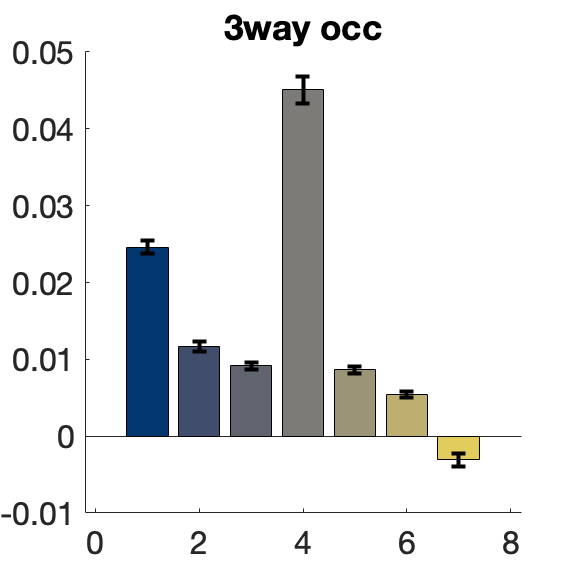

drawnow; pause(0.5);

% 3way occ
figure; ha; title('3way occ');
b=bar(x3,mPVAF_occ3);
b.FaceColor = 'flat';
b.CData = cmap3;
errorbar(x3,mPVAF_occ3,sPVAF_occ3,'LineStyle','none','Color','k','linewidth',2);
applytofig4keynote;

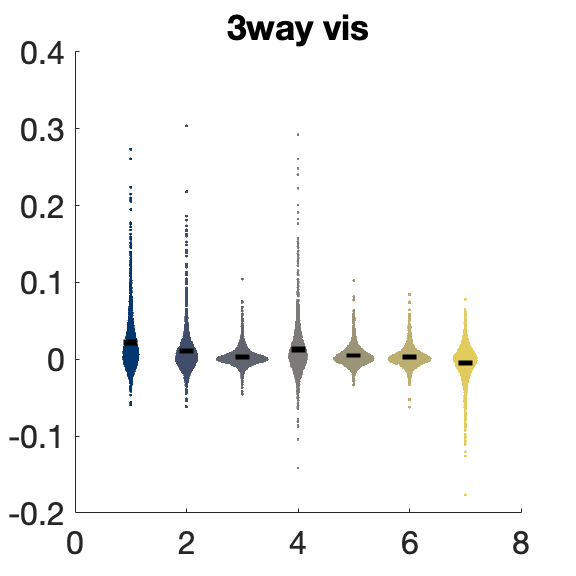

drawnow; pause(0.5);

% Swarmchart
% 3way vis
x3_2d=repmat(x3,size(PVAF_vis3,1),1); % 1385 x 7
cmap3_2d=repmat(cmap3,1,1,size(PVAF_vis3,1)); % 7 x 3 x 1385
cmap3_2d=shiftdim(cmap3_2d,1); % 3 x 1385 x 7
figure; ha; title('3way vis');
b=swarmchart(x3_2d(:),PVAF_vis3(:),1,cmap3_2d(:,:)','marker','.');
errorbar(x3,mPVAF_vis3,sPVAF_vis3,'LineStyle','none','Color','k','linewidth',2);
applytofig4keynote;

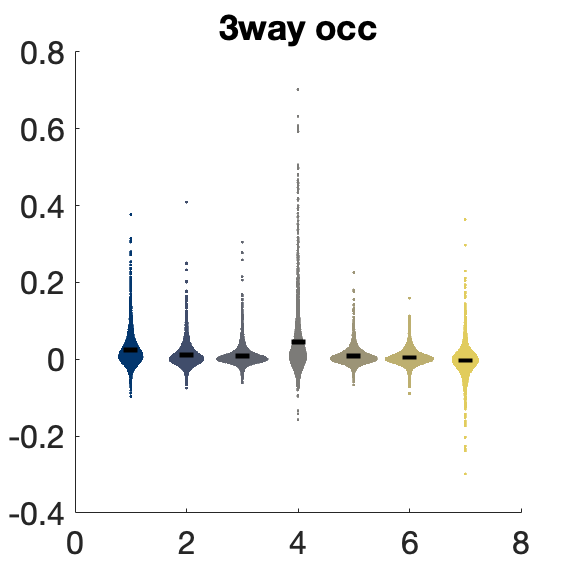

drawnow; pause(0.5);
% 3way occ
x3_2d=repmat(x3,size(PVAF_occ3,1),1); % 1385 x 7
cmap3_2d=repmat(cmap3,1,1,size(PVAF_occ3,1)); % 7 x 3 x 1385
cmap3_2d=shiftdim(cmap3_2d,1); % 3 x 1385 x 7
figure; ha; title('3way occ');
b=swarmchart(x3_2d(:),PVAF_occ3(:),1,cmap3_2d(:,:)','marker','.');
errorbar(x3,mPVAF_occ3,sPVAF_occ3,'LineStyle','none','Color','k','linewidth',2);
applytofig4keynote;

drawnow; pause(0.5);

% STAT
disp('visible');

visible


disp(mPVAF_vis3);

    0.0219    0.0106    0.0031    0.0130    0.0050    0.0034   -0.0044



disp(size(PVAF_vis3));

        1385           7



[p,h,stats]=signrank(PVAF_vis3(:,1),PVAF_vis3(:,4))

p = 5.8926e-11

h = logical
   1


stats = struct with fields:
          zval: 6.5464
    signedrank: 577362



disp('occluded');

occluded


disp(mPVAF_occ3);

    0.0246    0.0117    0.0091    0.0451    0.0086    0.0054   -0.0031



disp(size(PVAF_occ3));

        2576           7



[p,h,stats]=signrank(PVAF_occ3(:,1),PVAF_occ3(:,4))

p = 2.5217e-25

h = logical
   1


stats = struct with fields:
          zval: -10.3984
    signedrank: 1267015


[p,h,stats]=signrank(PVAF_occ3(:,1),PVAF_occ3(:,2))

p = 5.7315e-55

h = logical
   1


stats = struct with fields:
          zval: 15.6153
    signedrank: 2249115



return;

% swarmplot
X=repmat(x,n_neuron_vis,1);
figure; ha;
for i_label=1:size(X,2)
    swarmchart(X(:,i_label),PVAF_vis3(:,i_label),'.','Markerfacecolor',cmap3(i_label,:));
end
applytofig4keynote

X=repmat(x,n_neuron_occ,1);
figure; ha;
for i_label=1:size(X,2)
    swarmchart(X(:,i_label),PVAF_occ3(:,i_label),'.','Markerfacecolor',cmap3(i_label,:));
end
applytofig4keynote
return;

% venn diagram
% TBD: debug (maybe due to cross validation, PVAF(full model)<PVAF(reduced) sometimes

% for venn diagram
PVAF_vis=[V(:,1:3)...
    VI];
PVAF_occ=[O(:,1:3)...
    OI];

figure;
vennfig_vis = venn(nanmean(PVAF_vis(1:3),1),nanmean(PVAF_vis(4:end),1));
applytofig4keynote

figure;
vennfig_occ = venn(nanmean(PVAF_occ(1:3),1),nanmean(PVAF_occ(4:end),1));
applytofig4keynote
% scatter: ball-only vs rest with ball-related
PVAF_vis
% clustering? PCA?





function [Yval,Xval] = plot_histogram(x,b,i,cmap)

n=2;
markersize=4;
barWidth=0.4;

h=histogram(x,b);
Xval    = h.BinEdges + h.BinWidth*0.5 +h.BinWidth*(i-(n+1)/2)/2; % binWidth*0.25 for short, 0.75 for long
Xval    = Xval(1:end-1);Yval    = h.Values; delete(h);
hTmp      = bar(Xval,Yval,'BarWidth',barWidth,'FaceColor',cmap(i,:),'EdgeColor','none');
axis tight;
% plot mean
maxYlim=max(ylim);
plot(mean(x),1.1*maxYlim,'color',cmap(i,:),'markerfacecolor',cmap(i,:),'marker','v','markersize',markersize);
disp(mean(x)*100);

plotVertical(gca,0,[]); plotVertical(gca,1,[]);

% xlim([-0.05 1.05]);
set(gca,'xtick',0:0.2:1,'tickdir','out','ticklength',[0.02 0.02]); % ,'ytick',0:3:20
pause(0.1);


end
